# Electrode localization using FreeSurfer + iElectrodes

Written by Qian Chu (Max Planck - University of Toronto Centre)

Contact: qian.chu@{mail.utoronto.ca, ae.mpg.de, nyu.edu}

Version: 20230907

FreeSurfer version tested: 7.4.1

iElectrodes version tested: 1.020

## Checklist

Make sure that you have:

- Acquired the pre-op T1-weighted MRI scan (hereafter referred to as T1) in DICOM (.dcm) or NIFTI (.nii) format

- Acquired the post-op CT scan (hereafter referred to as CT)

- [Optional] Acquired the pre-op T2-weighted MRI scan (hereafter referred to as T2)

- FreeSurfer installed on this computer. FreeSurfer can be installed on Linux or MacOS. Download instructions: [https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads](https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads)

- Downloaded iElectrodes from [https://sourceforge.net/projects/ielectrodes/files/latest/download](https://sourceforge.net/projects/ielectrodes/files/latest/download) and put the unzipped package in this elec_loc folder.

## Run sections below one by one

## Setup

clearvars, clc, close all

Specify paths:

- To FreeSurfer home directory ($FREESURFER_HOME)

config.dir_fs = '/home/qian/research/freesurfer';

- To FreeSurfer subject directory ($SUBJECTS_DIR)

config.dir_fs_subjects = '/home/qian/research/fs_subjects';

FREESURFER_HOME and SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using *SetUpFreeSurfer.sh*

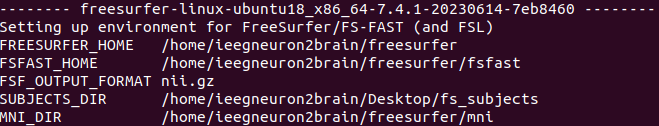

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, filesep);
elec_loc_dir        = strjoin(elec_loc_path_parts(1:end-1), filesep);

% Set up path
cd(elec_loc_dir)

iel_info = dir('iElectrodes*');
if isempty(iel_info)
    error(['No iElectrodes package detected. ' ...
        'Please download iElectrods from\n%s\n' ...
        'And move the unzipped folder to %s'], ...
        'https://sourceforge.net/projects/ielectrodes/files/ielectrodes/', ...
        elec_loc_dir)
end

addpath(genpath(iel_info.name))
addpath(genpath('functions'))
addpath(genpath('external'))

% Sanity if FreeSurfer directory is valid
fs_sanity_check(config)

## Convert DICOM to NIFTI

External package: [https://www.mathworks.com/matlabcentral/fileexchange/42997-xiangruili-dicm2nii](https://www.mathworks.com/matlabcentral/fileexchange/42997-xiangruili-dicm2nii)

Usually the raw brain scans (MRI & CT) are in DICOM (a folder of a series of .dcm files, one slice per file) format. For the convenience of processing, they need to be converted to a single NIFTI (.nii) file. **Make sure that .dcm files in one folder all belong to the same scan (i.e., dedicated T1/T2/CT folders).**

### Input

- [Select from GUI] Patient brain scan T1/T2/CT folder containing .dcm files

### Output

- A .nii file in the same folder

scan_dir = uigetdir('', 'Select the folder containing DICOM files of the brain scan');
dicm2nii(scan_dir, scan_dir, '.nii')

Validating 176 files ... (176 valid)
Converting 1 series (Siemens) into 4-D .nii: subject 'TWH207'
 x2_25_228976459994152948995670761797066486385             176x256x256x1
Elapsed time by dicm2nii is 1.6 seconds



## [Optional] De-identify the MRI scan(s)

[https://surfer.nmr.mgh.harvard.edu/fswiki/MiDeFace](https://surfer.nmr.mgh.harvard.edu/fswiki/MiDeFace)

MRI scan inevitably covers the face which makes it possible to reconize the patient's identity. De-facing is recommended for the sake of patient privacy should the scan be shared (e.g., for open data purposes). The FreeSurfer MiDeFace function performs a minimal modification of face voxels to achieve de-identification. The constrained yet sufficient de-facing process would ideally introduce very little influence on subsequent analyses, e.g. co-registration with CT.

De-facing takes ~10 minutes.

### Input

- [Select from GUI] T1/T2 scan

### Output

- De-faced T1 scan with suffix "_deface" in the same directory

### Post-execution behavior

- Freeview visualization of the de-faced scan as an isosurface for qualify check. The isosurface may take some moments to load.

- Adjust threshold on the bottom left if needed to visualize the whole face

- 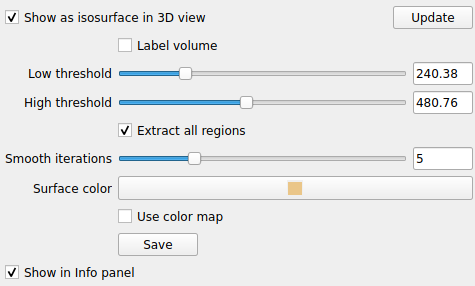

- If de-facing is satisfactory (identity unrecognizable), close Freeview to proceed

mideface(config)

Wed 25 Oct 2023 04:55:55 PM EDT

setenv SUBJECTS_DIR /home/qian/research/fs_subjects
cd /home/qian/Documents/GitHub/elec_loc
/home/qian/research/freesurfer/bin/mideface --i /home/qian/Downloads/TWH207/T1/x2_25_71562999742196548089054911652232629837.nii --o /home/qian/Downloads/TWH207/T1/x2_25_71562999742196548089054911652232629837_deface.nii
-rwxrwxr-x 1 qian qian 29151 Jun 14 00:19 /home/qian/research/freesurfer/bin/mideface

freesurfer-linux-ubuntu20_x86_64-7.4.1-20230614-7eb8460
$Id$
Linux N2B-KDT 5.15.0-83-generic #92~20.04.1-Ubuntu SMP Mon Aug 21 14:00:49 UTC 2023 x86_64 x86_64 x86_64 GNU/Linux
pid 2011149
UseXvfb 0
samseg --i /home/qian/Downloads/TWH207/T1/x2_25_71562999742196548089054911652232629837.nii --o /home/qian/Downloads/TWH207/T1/tmpdir.mideface.2011149/samseg --threads 1 --block-coordinate-descent --options /home/qian/research/freesurfer/average/mideface-atlas/samseg-options.json
~/Downloads/TWH207/T1/tmpdir.mideface.2011149/samseg ~/Documents/GitHub/elec_loc 
~/Documen

## [Optional] Align T1 scan to AC-PC line

This program relies on the FreeSurfer full reconstruction pipieline known as "recon-all". The input for recon-all is the T1 scan, preferrably aligned to AC-PC line. If you would like to do this pre-recon alignment, you can easily do so in Freeview, the visualization tool in FreeSurfer.

- Open Freeview by typing "freeview" in your terminal or by running the code below

- File > Load Volume, select the T1 scan

- Tools > Transform Volume

- Use the "Rotate" and "Translate" tools to align

- Use "Save Volume as" button to save the transformed scan

Code for selecting a T1 scan and opening it in Freeview:

[t1_ali_name, t1_ali_dir] = uigetfile({'*.nii; *.nii.gz; *.mgz'}, ...
    'Select T1 scan');
t1_ali_path = fullfile(t1_ali_dir, t1_ali_name);

bash_code = sprintf('%s; freeview -v %s', ...
    fs_setup_code(config), t1_ali_path);

system(bash_code);

## Run FreeSurfer recon-all if not done already

[https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all](https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all)

"recon-all" is a command line script in FreeSurfer. The name comes from "reconstruction of all structures," and this command calls a series of scripts for preprocessing, segmentation, and cortical surface reconstruction.

### Inputs

- [Type in field below] Patient ID

- [Select from GUI] Patient T1 scan (could be de-faced and/or aligned to AC-PC though both are optional)

### Outputs

- FreeSurfer subject folder *$SUBJECTS_DIR/PATIENT_NAME*

After executing, wait a few minutes to make sure recon-all initiates without errors. The execution takes **10 hours or more **so it might be a good idea to run it overnight. Lay down .... ;)

pat.name = "TWH207";
pat = fs_recon_all(config, pat);

fs-check-version --s TWH207 --o /tmp/tmp.ZUqLlp
Wed Oct 25 17:16:08 EDT 2023

setenv SUBJECTS_DIR /home/qian/research/fs_subjects
cd /home/qian/Documents/GitHub/elec_loc
/home/qian/research/freesurfer/bin/fs-check-version --s TWH207 --o /tmp/tmp.ZUqLlp
-rwxrwxr-x 1 qian qian 18565 Jun 14 00:19 /home/qian/research/freesurfer/bin/fs-check-version

freesurfer-linux-ubuntu20_x86_64-7.4.1-20230614-7eb8460
$Id$
Linux N2B-KDT 5.15.0-83-generic #92~20.04.1-Ubuntu SMP Mon Aug 21 14:00:49 UTC 2023 x86_64 x86_64 x86_64 GNU/Linux
pid 2013710
Current FS Version freesurfer-linux-ubuntu20_x86_64-7.4.1-20230614-7eb8460
Subject does not have a bstampfile, copying /home/qian/research/freesurfer/build-stamp.txt
Subject FS Version: freesurfer-linux-ubuntu20_x86_64-7.4.1-20230614-7eb8460
No constraints on version because REQ=UnSet and FsVerFile=NotThere
#@#% fs-check-version match = 1
fs-check-version Done
INFO: SUBJECTS_DIR is /home/qian/research/fs_subjects
Actual FREESURFER_HOME /home/qian/research/free

## [If you have run recon-all before] Select FreeSurfer subject folder

If you have run recon-all outside of this script, simply tell it where the output folder is. The script automatically takes the selected folder name as patient name.

pat = fs_find_subj(config);

Patient TWH208 selected
FreeSurfer folder at /home/qian/research/fs_subjects/TWH208

## Convert .mgz to .nii

Some FreeSurfer .mgz output files are used by iElectrodes, yet iElectrodes only recognizes NIFTI (.nii). The function below does a stacked conversion.

### Inputs

- [Auto-loaded] .mgz files in "mri" subfolder

### Outputs

- .nii files in "mri" subfolder

mgz2nii(config, pat)

Converting .mgz to .nii in /home/qian/research/fs_subjects/TWH208/mri
mri_convert --in_type mgz --out_type nii --out_orientation RAS /home/qian/research/fs_subjects/TWH208/mri/T1.mgz /home/qian/research/fs_subjects/TWH208/mri/T1.nii 
reading from /home/qian/research/fs_subjects/TWH208/mri/T1.mgz...
TR=2200.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, -1.73472e-18, -4.54747e-13)
j_ras = (-4.54747e-13, -4.54747e-13, -1)
k_ras = (0, 1, 4.54747e-13)
Setting output orientation to RAS
Reslicing using trilinear interpolation 
writing to /home/qian/research/fs_subjects/TWH208/mri/T1.nii...
mri_convert --in_type mgz --out_type nii --out_orientation RAS /home/qian/research/fs_subjects/TWH208/mri/aparc+aseg.mgz /home/qian/research/fs_subjects/TWH208/mri/aparc+aseg.nii 
reading from /home/qian/research/fs_subjects/TWH208/mri/aparc+aseg.mgz...
TR=2200.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, -1.73472e-1

## Import CT to subject folder

From now on we will utilize the FreeSurfer subject folder (*$SUBJECTS_DIR/PATIENT_NAME*) to store files for this script.

### Input

- [Select from GUI] CT scan

### Output

- Imported CT scan at *ct/postop_ct.nii*

import_ct(config, pat)

mri_convert 
				Help

NAME
	mri_convert

SYNOPSIS
	mri_convert [options] <in volume> <out volume>

DESCRIPTION
	mri_convert is a general purpose utility for converting between 
	different file formats. The file type can be specified in two ways. 
	First, mri_convert will try to figure it out on its own from the 
	format of the file name (eg, files that end in .img are assumed to be 
	in spm analyze format). Second, the user can explicity set the type of
	file using --in_type and/or --out_type.
	
	Legal values for --in_tye (-it) and --out_type (-ot) are listed under 
	optional flagged arguments.
	
	A note on specifying orientation:
	
	Do not use this to try to change the orientation for FSL. This is only
	to be used when the orientation information in the input file is 
	*wrong*. If it is correct, this will make it wrong! If you are having 
	problems with fslview displaying your data, consult the FSL website 
	for methods to reorient.
	
	Ideally, the orientation information is derived 

## Co-register CT to T1 MRI

### Inputs

- [Select from dropdown box] Co-registration method ("freesurfer" or "spm")

- [Auto-loaded] CT scan at *ct/postop_ct.nii*

- [Auto-loaded] T1 scan at *mri/nu.nii*

### Output

If using FreeSurfer's mri_coreg ([https://surfer.nmr.mgh.harvard.edu/fswiki/mri_coreg](https://surfer.nmr.mgh.harvard.edu/fswiki/mri_coreg)):

- CT aligned to T1 space: *ct/postop_ct_coreg_fs.nii*

- Transformation matrix: *ct/ct2t1.lta*

If using SPM's spm_coreg ([https://github.com/spm/spm12/blob/master/spm_coreg.m](https://github.com/spm/spm12/blob/master/spm_coreg.m)):

- CT aligned to T1 space: *ct/postop_ct_coreg_spm.nii*

- Transformation matrix: *ct/ct2t1.mat*

### Post-execution behavior

- Freeview visualization of the co-registered CT on top of the T1 scan

- Check how well the skull imaged by T1 (usually dark) and CT (high-intensity) agree on each other. You can uncheck the "post_op_ct_coreg_*" layer to view exclusively T1

- If co-registration is satisfactory, close Freeview to proceed

- If not, a manual co-registration might be needed. To do so, transform CT using Freeview tools described in the [Optional] Align T1 scan to AC-PC line section. For instructions see step 3 of [https://www.protocols.io/view/modular-reconstruction-and-co-registration-of-imag-5qpvornedv4o/v2?step=3.](https://www.protocols.io/view/modular-reconstruction-and-co-registration-of-imag-5qpvornedv4o/v2?step=3.)

method = "freesurfer";
t1_ct_coreg(config, pat, method)


$Id: mri_coreg.c,v 1.27 2016/04/30 15:11:49 greve Exp $
cwd /home/qian/Documents/GitHub/elec_loc
cmdline mri_coreg --mov /home/qian/research/fs_subjects/TWH208/ct/postop_ct.nii --targ /home/qian/research/fs_subjects/TWH208/mri/nu.nii --reg /home/qian/research/fs_subjects/TWH208/ct/ct2t1.dat --lta /home/qian/research/fs_subjects/TWH208/ct/ct2t1.lta 
sysname  Linux
hostname N2B-KDT
machine  x86_64
user     qian
dof    6
nsep    2
cras0    1
ftol    0.000000
linmintol    0.001000
bf       1
bflim    30.000000
bfnsamp    30
SmoothRef 0
SatPct    99.990000
MovOOB 0
optschema 1
Seed 53
Reading in mov /home/qian/research/fs_subjects/TWH208/ct/postop_ct.nii
Reading in ref /home/qian/research/fs_subjects/TWH208/mri/nu.nii
Setting cras translation parameters to align volume centers
Init matrix params -4.0825  6.8638 -717.7494  0.0000  0.0000  0.0000  1.0000  1.0000  1.0000  0.0000  0.0000  0.0000 
Initial Matrix (RAS2RAS)
 1.00000   0.00000   0.00000   4.08251;
 0.00000   1.00000   0.00000  -6.

## [Optional] Import T2 to subject folder

The T2 scan is not used anywhere in this script, but some people may need it for other purposes (e.g., subfield segmentation) so let's include it in the folder.

### Input

- [Select from GUI] T2 scan

### Output

- Imported T2 scan at *t2/t2.nii*

import_t2(config, pat)

T2 image copied to /home/qian/research/fs_subjects/TWH207/t2/t2.nii

## [Optional] Co-register T2 to T1

All similar to Co-register CT to T1 MRI but for T2-T1 co-registration

method = "freesurfer";
t1_t2_coreg(config, pat, method)


$Id: mri_coreg.c,v 1.27 2016/04/30 15:11:49 greve Exp $
cwd /home/qian/Documents/GitHub/elec_loc
cmdline mri_coreg --mov /home/qian/research/fs_subjects/TWH207/t2/t2.nii --targ /home/qian/research/fs_subjects/TWH207/mri/nu.nii --reg /home/qian/research/fs_subjects/TWH207/t2/t2_to_t1.dat --lta /home/qian/research/fs_subjects/TWH207/t2/t2_to_t1.lta 
sysname  Linux
hostname N2B-KDT
machine  x86_64
user     qian
dof    6
nsep    2
cras0    1
ftol    0.000000
linmintol    0.001000
bf       1
bflim    30.000000
bfnsamp    30
SmoothRef 0
SatPct    99.990000
MovOOB 0
optschema 1
Seed 53
Reading in mov /home/qian/research/fs_subjects/TWH207/t2/t2.nii
Reading in ref /home/qian/research/fs_subjects/TWH207/mri/nu.nii
Setting cras translation parameters to align volume centers
Init matrix params  0.9000 -0.7254  5.3940  0.0000  0.0000  0.0000  1.0000  1.0000  1.0000  0.0000  0.0000  0.0000 
Initial Matrix (RAS2RAS)
 1.00000   0.00000   0.00000  -0.89999;
 0.00000   1.00000   0.00000   0.72541;
 0.

## [Optional] Hippocampus/amygdala segmentation

[https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala](https://surfer.nmr.mgh.harvard.edu/fswiki/HippocampalSubfieldsAndNucleiOfAmygdala)

### Input

- [Select from dropdown box] Scan(s) to use ("T1" or "T2" or "T1+T2")

- [Auto-loaded] T1 and T2

### Output

- Hippocampus/amygdala segmentation results under *mri *directory

scan_to_use = "T1";
fs_hpc_amy_seg(config, pat, scan_to_use)

## Electrode labeling using iElectrodes

In this pipeline we use [iElectrodes](https://sourceforge.net/p/ielectrodes/wiki/Home/), an easy-to-use and robust toolbox for localizing intracranial electrodes. The code in this section creates a new subfolder to store localization outputs (*iel*) and launches iElectrodes

Welcome to iElectrodes.
iElectrodes toolbox is FOR RESEARCH PURPOSES ONLY. This software is
for research purposes only and has NOT BEEN APPROVED FOR CLINICAL USE.
Help about using iElectrodes can be found online in 
https://sourceforge.net/p/ielectrodes/wiki/Home/
You have the last version of iElectrodes :-)
Project estructure is beeing checked...
Checking done.


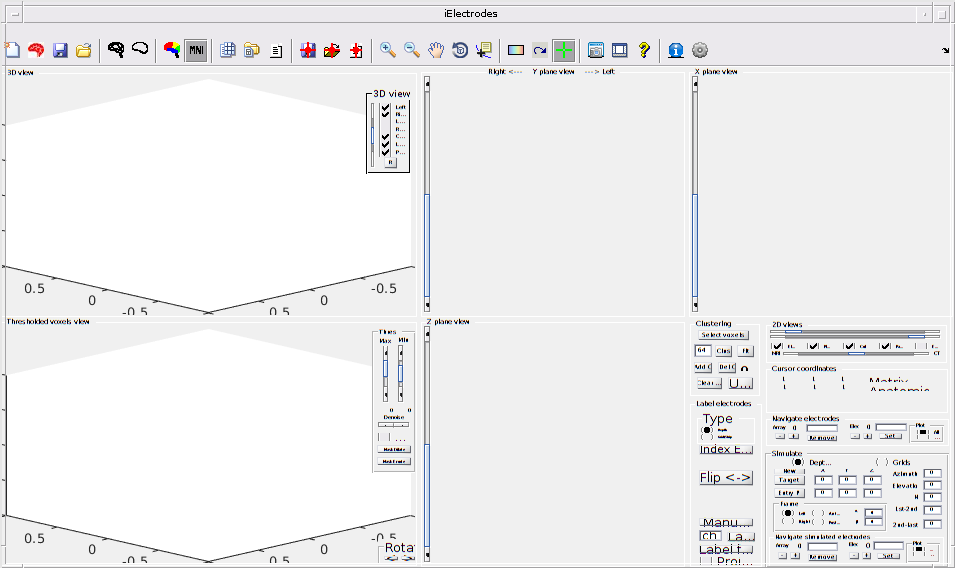

iel_dir = fullfile(pat.dir, 'iel');
if ~exist(iel_dir, 'dir'), mkdir(iel_dir), end

cd(pat.dir)
electrodes_gui

### iElectrodes toolbars

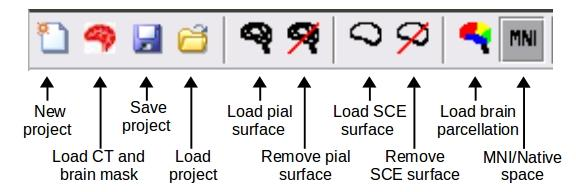

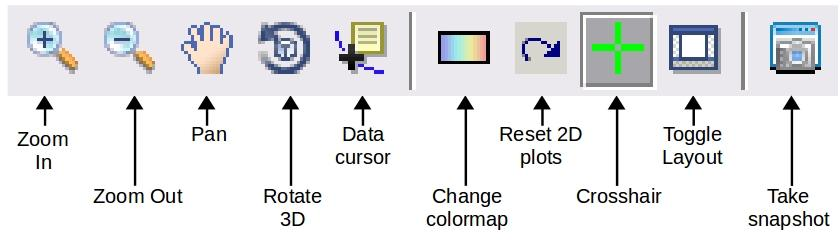

### Steps

- Click "New project" (see icon above) and load *mri/nu.nii.* T1 scan will appear on the top right corner of the iElectrodes window once loading is complete

- Click "Load CT and brain mask" (see icon above). You will be prompted to select the CT scan at *ct/postop_ct_coreg_<method>.nii*. After a while, you will be prompted again to select the brain mask. You can load the co-registered CT again. Using other masks like ribbon.nii might make it hard to visualize other landmarks like bolts, which are sometimes useful when navigating electrode locations.

- Follow [this tutorial](https://sourceforge.net/p/ielectrodes/wiki/Localization%20and%20labeling%20of%20intracranial%20electrodes/) to threshold CT, select above-threshold voxels, cluster and label electrodes.

- You can always save your progress at any stage by clicking "Save project" (see icon above). The saved .iel file should contain all the necessary components to retrieve your progress.

- After you are done, click 'Save/Export Electrodes' (see icon below) to save the electrode outputs in various forms. For generating the label tables in later steps, select the second output option to generate a plain txt file with channel name and XYZ coordinates in the native T1 space. It is recommended that you save it as *iel/PATIENT_NAME_elec.txt* (e.g., TWH001_elec.txt)

 

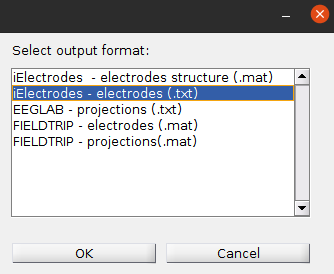

## [If using Behke-Fried depth electrodes] Estimate microwire location

iElectrodes cannot properly recognize microwires (which may or may not be visible on a post-op CT). A workaround is to estimate their location using locations of the 1st and 2nd electrodes (deepest two) and the distance between the first electrode and the microwire bundle.

### Input

- [Select from GUI] Electrode location .txt file

- [Type in field below] Known distance from the microwire bundle to the deepest macro contact (specify in code below)

### Output

- New electrode location .txt file with suffix "_u" in the same folder

% Specify distance from the microwire bundle to the deepest macro contact
% (in mm)
micro_to_macro_dist = 3;

% Select the electrode output .txt file
estimate_micro(pat, micro_to_macro_dist)

No microwire found for LAHC     Estimating... 
No microwire found for LAMG     Estimating... 
No microwire found for LPHC     Estimating... 
No microwire found for LPHG     Estimating... 
No microwire found for RAHC     Estimating... 
No microwire found for RAMG     Estimating... 
No microwire found for RPHC     Estimating... 
No microwire found for RPHG     Estimating... 
New txt saved: /home/qian/research/fs_subjects/TWH208/iel/TWH208_elec_u.txt


## Get FreeSurfer labels in the native space

Since recon-all also produces brain segmentation and parcellation, we can automatically read the label value for each electrode from <aparc.***.mgz> files and find the corresponding label from *$FREESURFER_HOME/FreeSurferColorLUT.txt*. For details of the parcellations see [https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation](https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation)

### Input

- [Select from GUI] Electrode location .txt file (can be the output of microwire position estimation)

### Output

- Electrode location table (in native space) at *iel/PATIENT_NAME_elec_native.csv*

label_native(config, pat)

Electrode location (native space) table saved at: /home/qian/research/fs_subjects/TWH208/iel/TWH208_elec_native.csv


## Get electrode coordinates in MNI305 and MNI152 space [PENDING FREESURFER COMMUNITY REVIEW]

For group-level visualization of electrode location, mapping locations from native to standardized spaces is usually helpful. This section does two linear transforms to electrode locations to map them to:

- MNI305, also known as the fsaverage space. FreeSurfer automatically co-registers the native T1 onto this space and stores the native-to-MNI305 transformation matrix at *mri/transforms/talairach.xfm.*

- MNI152 space. The MNI305-to-MNI152 matrix is provided in [https://surfer.nmr.mgh.harvard.edu/fswiki/CoordinateSystems](https://surfer.nmr.mgh.harvard.edu/fswiki/CoordinateSystems).

In addition to generating location tables just like in the previous section, the code also automatically generates .node files. These are useful for visualizing electrode locations in some other softwares (e.g., BrainNet Viewer, Surf Ice). Below is an example visualization of *_elec_mni152.node in BrainNet Viewer:

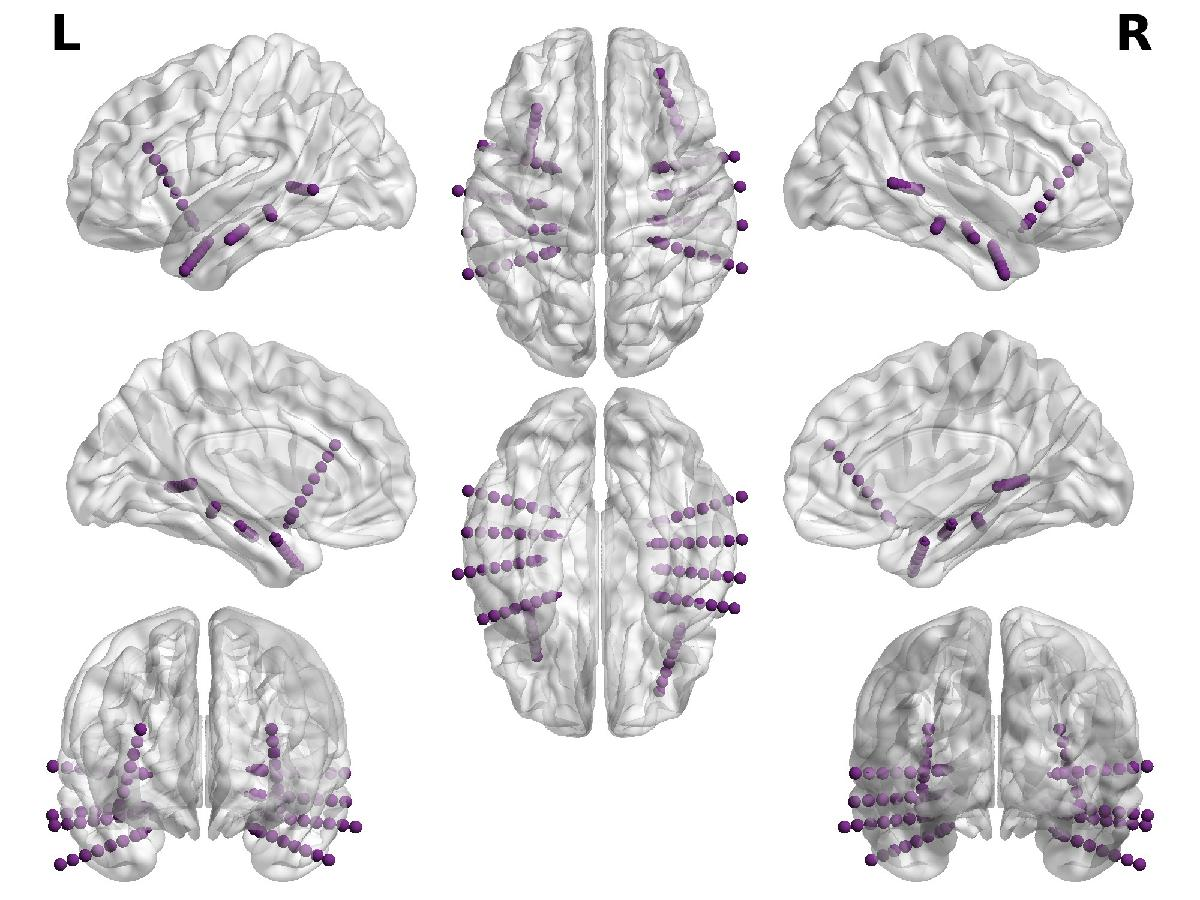

### Input

- [Select from GUI] Electrode location .txt file (can be the output of microwire position estimation)

### Output

- Electrode location table (in MNI305/fsaverage) at *iel/PATIENT_NAME_elec_mni305.csv*

- Electrode location node file (in MNI305/fsaverage) at *iel/PATIENT_NAME_elec_mni305.node*

- Electrode location table (in MNI152) at *iel/PATIENT_NAME_elec_mni152.csv*

- Electrode location node file (in MNI152) at *iel/PATIENT_NAME_elec_mni152.node*

label_mni(pat)

Electrode location (MNI305 space) table saved at: /home/qian/research/fs_subjects/TWH208/iel/TWH208_elec_mni305.csv
Electrode location (MNI152 space) table saved at: /home/qian/research/fs_subjects/TWH208/iel/TWH208_elec_mni152.csv
Electrode location (MNI305 space) node saved at: /home/qian/research/fs_subjects/TWH208/iel/TWH208_elec_mni305.node
Electrode location (MNI152 space) node saved at: /home/qian/research/fs_subjects/TWH208/iel/TWH208_elec_mni152.node
